Group 4

Saifelden Ismail 202100432

% importing all of the data from the directory
clear;

currentFilePath = matlab.desktop.editor.getActiveFilename();
[currentDir, ~, ~] = fileparts(currentFilePath);

files = dir(currentDir);

matFiles = dir(fullfile(currentDir, '*.mat'));
for i = 1:length(matFiles)
    filePath = fullfile(currentDir, matFiles(i).name);
    [~, varName, ~] = fileparts(matFiles(i).name);
    assignin('base', varName, load(filePath));
    fprintf("Loaded '%s' into variable '%s'\n", matFiles(i).name, varName);
end

Loaded 'chb12_29_data.mat' into variable 'chb12_29_data'
Loaded 'chb12_29_header.mat' into variable 'chb12_29_header'
Loaded 'chb12_32_data.mat' into variable 'chb12_32_data'
Loaded 'chb12_32_header.mat' into variable 'chb12_32_header'


% create the seizure signals and the non seizure signals
% File Start Time: 18:07:19
% File End Time: 19:07:43
% Number of Seizures in File: 6
% Seizure 1 Start Time: 107 seconds
% Seizure 1 End Time:  146 seconds
% Seizure 2 Start Time: 554 seconds
% Seizure 2 End Time:  592 seconds
% Seizure 3 Start Time: 1163 seconds
% Seizure 3 End Time:  1199 seconds
% Seizure 4 Start Time: 1401 seconds
% Seizure 4 End Time:  1447 seconds
% Seizure 5 Start Time:  1884 seconds
% Seizure 5 End Time: 1921 seconds
% Seizure 6 Start Time: 3557 seconds
% Seizure 6 End Time: 3584 seconds

%sample rate 256

EEG_data_1 = chb12_29_data.data;
sampling_rate = 256;

%taking the data and placing it inside a variable
EEG_data_1 = chb12_29_data.data;
sampling_rate = 256;
%splicing all of the seizure sections specified in the document
s1 = EEG_data_1(sampling_rate * 107:sampling_rate * 146, :);
s2 = EEG_data_1(sampling_rate * 554:sampling_rate * 592, :);
s3 = EEG_data_1(sampling_rate * 1163:sampling_rate * 1199, :);
s4 = EEG_data_1(sampling_rate * 1401:sampling_rate * 1447, :);
s5 = EEG_data_1(sampling_rate * 1884:sampling_rate * 1921, :);
s6 = EEG_data_1(sampling_rate * 3557:sampling_rate * 3584, :);



%putting them together
combined_seizures = [s1; s2; s3; s4; s5; s6];


%Placing the non_siezure_signal_together
non_seizure_signal = [EEG_data_1(1:sampling_rate * 107, :);
                      EEG_data_1(sampling_rate * 146+1:sampling_rate * 554, :);
                      EEG_data_1(sampling_rate * 592+1:sampling_rate * 1163, :);
                      EEG_data_1(sampling_rate * 1199+1:sampling_rate * 1401, :);
                      EEG_data_1(sampling_rate * 1447+1:sampling_rate * 1884, :);
                      EEG_data_1(sampling_rate * 1921+1:sampling_rate * 3557, :);
                      EEG_data_1(sampling_rate * 3584+1:end, :)];





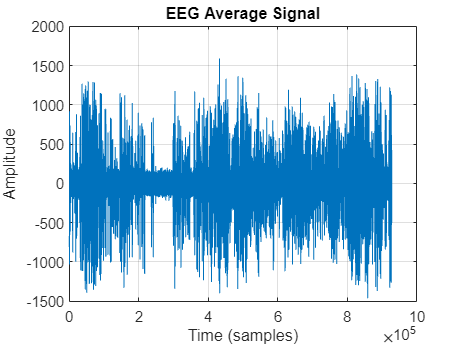





%averaging channels
% SELECT CHANNELS TO AVERAGE AND PRESS RUN


channel_1=true;channel_2=true;channel_3=true;channel_4=false;channel_5=false;
channel_6=true;channel_7=true;channel_8=true;channel_9=false;channel_10=true;
channel_11=false;channel_12=true;channel_13=true;channel_14=false;channel_15=false;
channel_16=false;channel_17=true;channel_18=false;channel_19=false;channel_20=false;
channel_21=false;channel_22=true;channel_23=false;channel_24=false;channel_25=false;
channel_26=false;channel_27=false;channel_28=false;channel_29=false;

channel_all=true;
 


channels=[channel_1, channel_2, channel_3, channel_4, channel_5, channel_6, ...
    channel_7, channel_8, channel_9, channel_10, channel_11,...
    channel_12, channel_13, ...
    channel_14, channel_15, channel_16, channel_17, channel_18, ...
    channel_19, channel_20, ...
    channel_21, channel_22, channel_23, channel_24, channel_25,...
    channel_26, channel_27, ...
    channel_28, channel_29];

selected_channels=find(channels | channel_all);


EEG_average_signal=tsnansum(chb12_29_data.data(:,selected_channels),2)...
    /length(selected_channels);
EEG_average_seizure_signal=tsnansum(combined_seizures(:,selected_channels),2)...
    /length(selected_channels);
EEG_average_non_seizure_signal=tsnansum(non_seizure_signal(:,selected_channels),2)...
    /length(selected_channels);

figure;
plot(EEG_average_signal);
title('EEG Average Signal');
xlabel('Time (samples)');
ylabel('Amplitude');
grid on;

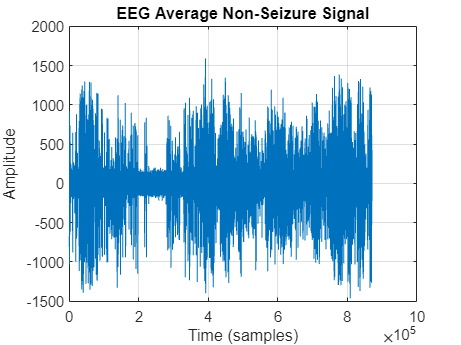


figure;
plot(EEG_average_non_seizure_signal);
title('EEG Average Non-Seizure Signal');
xlabel('Time (samples)');
ylabel('Amplitude');
grid on;

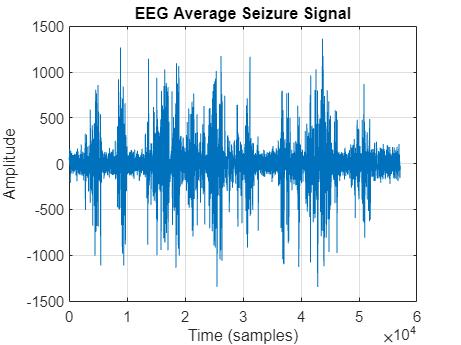


figure;
plot(EEG_average_seizure_signal);
title('EEG Average Seizure Signal');
xlabel('Time (samples)');
ylabel('Amplitude');
grid on;

%window creation, and setting variables that would be needed for a
%spectrogram. beginning to build a function
overlap=0

overlap = 0

window_length=2

window_length = 2

%window length is set in seconds, it is the value of "n" listed in the
%document. multiplying sampling rate by window length gives us the segment
%length
segment_length=sampling_rate*window_length;
%step size is what we'll use in the loop, this will lengthen the time axis.
step_size=segment_length-overlap;
%M as defined in the document
M=segment_length-1

M = 511

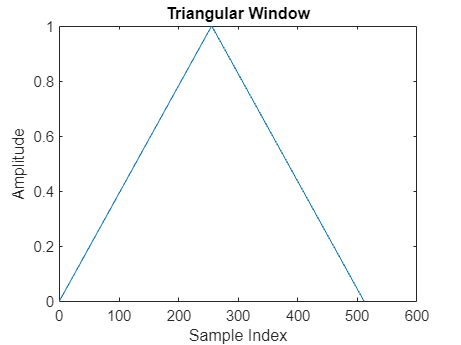

%time that will be used do define our windows
t=linspace(0,M,segment_length);
window_rectangular=ones(1,segment_length);
window_triangular=[linspace(0,1,segment_length/2),linspace(1,0,segment_length/2)];
window_hamming=0.54 - 0.46 * cos(2*pi* t/M);
window_blackman=0.42 - 0.5* cos(2* pi*t /M) + 0.08 * cos(4*pi*t/M);
%window definition as listed in document
%the windows matrix contains each window in its own column, will be used
%for function so that i can give a numerical input and that will define
%which window you'll use (ie, 1 is rect, 2 is tri, 3 is hamming, 4 is
%blackman)
windows=[window_rectangular;window_triangular;window_hamming;window_blackman;];
selected_window=transpose(windows(1,:));
%transposing the selected window to match the column vector used for
%average EEG data

%PLOTTING WINDOWS FOR ILLUSTRATION PURPOSES
plot(t,abs( window_triangular));
title('Triangular Window');
xlabel('Sample Index');
ylabel('Amplitude');

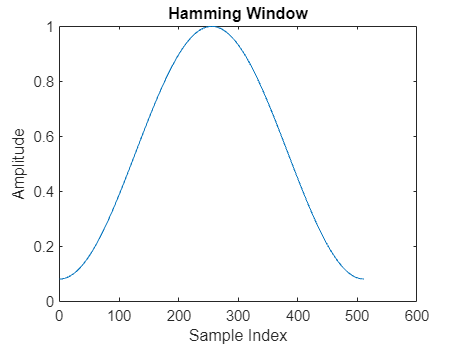



plot(t,window_hamming);
title('Hamming Window');
xlabel('Sample Index');
ylabel('Amplitude');

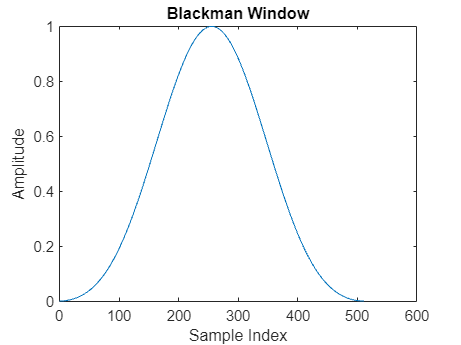


plot(t,window_blackman);
title('Blackman Window');
xlabel('Sample Index');
ylabel('Amplitude');


%testing the LENGTH and WIDTH of the EEG using equations (unnecesary code,
%used for experimentation)
time_axis_size=((length(EEG_average_signal)-overlap)/(segment_length)-overlap);
number_of_frequency_bins=segment_length/2 +1;


% test run!, 
%writing the main loop. consists of taking the segment, multipying it with
%the window and then applying a fourrier transforming and adding the column
%to the spectrogram. the same steps are used below to make the function
spectrogram=[];
for step = segment_length:step_size:length(EEG_average_signal)
    lower_index=step-segment_length+1;
    segment=EEG_average_signal(lower_index:step);
    windowed_segment=selected_window.*segment;
    STFT=fft(windowed_segment);
    spectrogram=[spectrogram,STFT];
end

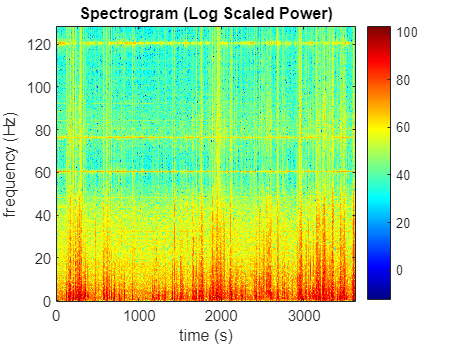

%plotting. Log scale for better visibiliy and showing the image like a
%colormap to mimic spectrogram
power=20*log10(abs(spectrogram));
%FFT is mirrored, remove the top half of the mirrored signal 
power=power(1:height(power)/2,:);
% generate the time, and frequency vectors
time = linspace(0, length(EEG_average_signal)/sampling_rate, size(power, 2));
freq = linspace(0, sampling_rate / 2, size(power, 1)); 

imagesc(time,freq,power);

colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title('Spectrogram (Log Scaled Power)');

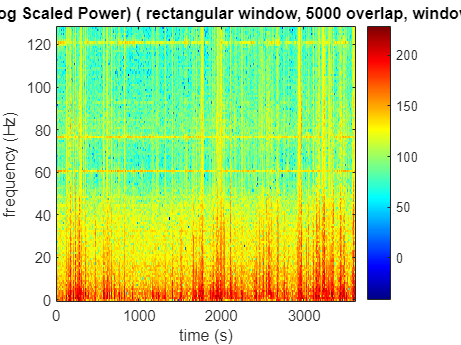



%SHOWING THE DIFFERENCES IN THE ABNORMAL AND NORMAL EEG
[sp1, time, freq]= spectrogram_calculate(EEG_average_signal, ...
    sampling_rate,1,0,1);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) ' ...
    '( rectangular window, 5000 overlap, window size 20)']);

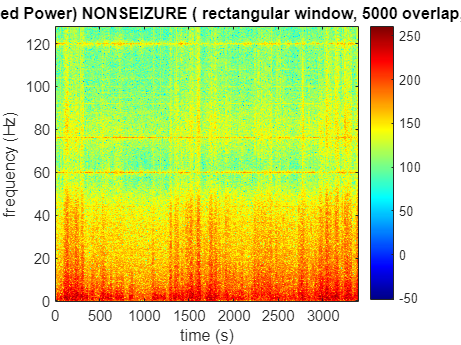


[sp1, time, freq]= spectrogram_calculate(EEG_average_non_seizure_signal, ...
    sampling_rate,1,5000,20);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) NONSEIZURE ' ...
    '( rectangular window, 5000 overlap, window size 20)']);

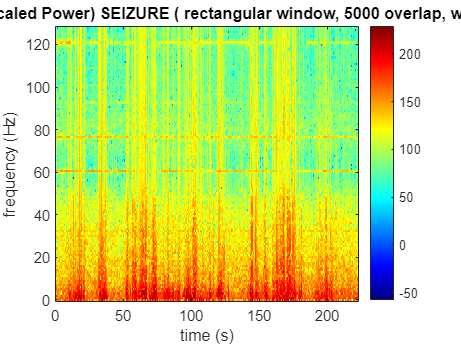


[sp1, time, freq]= spectrogram_calculate(EEG_average_seizure_signal, ...
    sampling_rate,1,255,1);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) SEIZURE' ...
    ' ( rectangular window, 5000 overlap, window size 20)']);

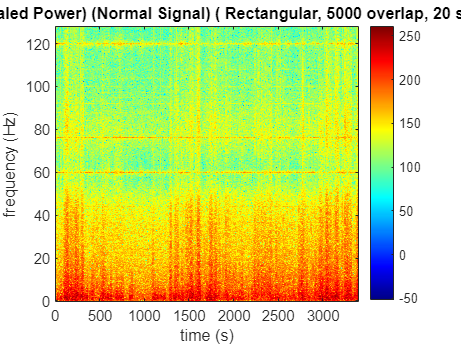


%SHOWING DIFFERENT WINDOW TYPES AND DIFFERENT WINDOW LENGTHS NORNOMAL
[sp1, time, freq]= spectrogram_calculate(EEG_average_non_seizure_signal ...
    ,sampling_rate,1,5000,20);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (Normal Signal)' ...
    ' ( Rectangular, 5000 overlap, 20 second window)']);

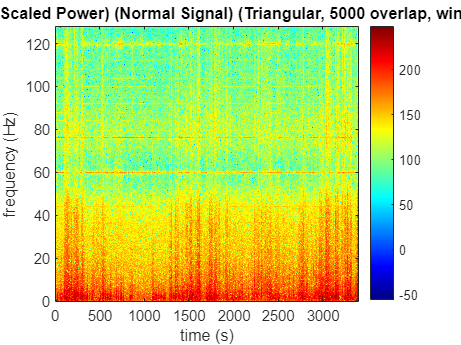



%using our function
[sp1, time, freq]= spectrogram_calculate(EEG_average_non_seizure_signal, ...
    sampling_rate,2,5000,20);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (Normal Signal)' ...
    ' (Triangular, 5000 overlap, window size 20)']);

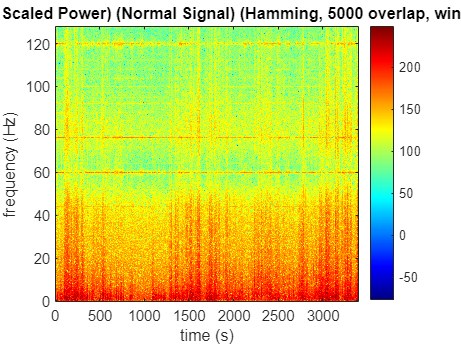

%using our function
[sp1, time, freq]= spectrogram_calculate(EEG_average_non_seizure_signal, ...
    sampling_rate,3,5000,20);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (Normal Signal)' ...
    ' (Hamming, 5000 overlap, window size 20)']);

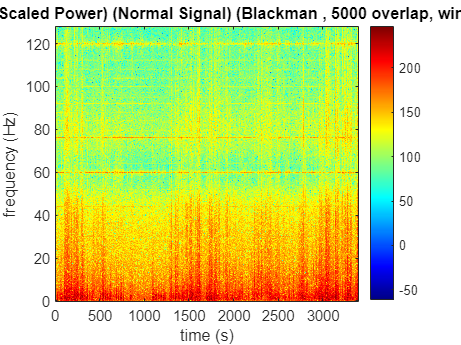



%using our function
[sp1, time, freq]= spectrogram_calculate(EEG_average_non_seizure_signal, ...
    sampling_rate,4,5000,20);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (Normal Signal)' ...
    ' (Blackman , 5000 overlap, window size 20)']);

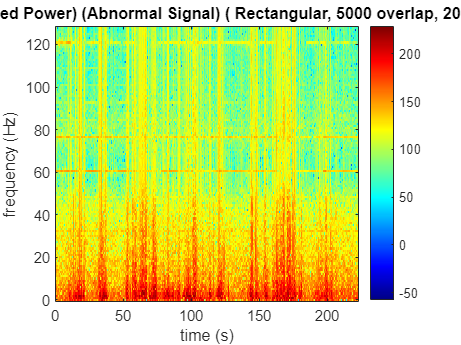


%SHOWING DIFFERENT WINDOW TYPES AND DIFFERENT WINDOW LENGTHS ABNORMAL
[sp1, time, freq]= spectrogram_calculate(EEG_average_seizure_signal, ...
    sampling_rate,1,255,1);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (Abnormal Signal)' ...
    ' ( Rectangular, 5000 overlap, 20 second window)']);

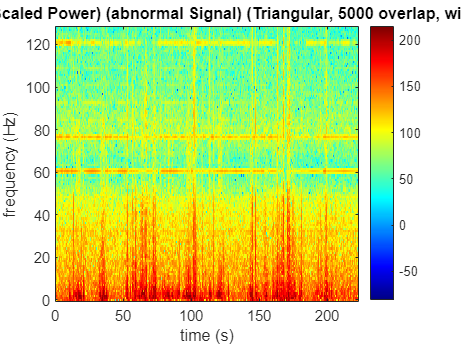



%using our function
[sp1, time, freq]= spectrogram_calculate(EEG_average_seizure_signal, ...
    sampling_rate,2,255,1);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (abnormal Signal)' ...
    ' (Triangular, 5000 overlap, window size 20)']);

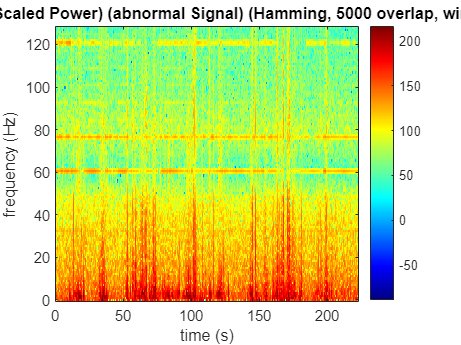

%using our function
[sp1, time, freq]= spectrogram_calculate(EEG_average_seizure_signal, ...
    sampling_rate,3,255,1);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (abnormal Signal)' ...
    ' (Hamming, 5000 overlap, window size 20)']);

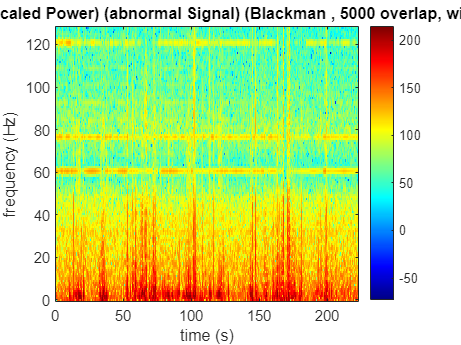



%using our function
[sp1, time, freq]= spectrogram_calculate(EEG_average_seizure_signal, ...
    sampling_rate,4,255,1);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (abnormal Signal)' ...
    ' (Blackman , 5000 overlap, window size 20)']);

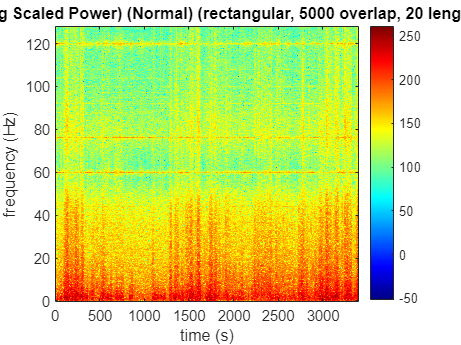


%APPLYING DIFFERENT OVERLAP RATIOS NORMAL

[sp1, time, freq]= spectrogram_calculate(EEG_average_non_seizure_signal, ...
    sampling_rate,1,5000,20);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (Normal)' ...
    ' (rectangular, 5000 overlap, 20 length window)']);

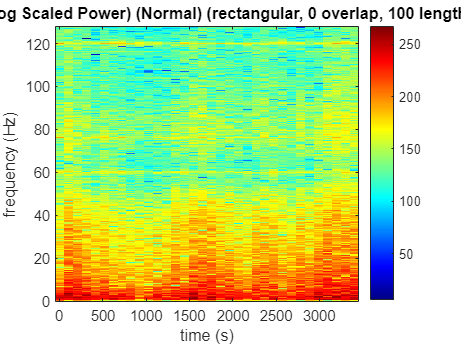


%using our function
[sp1, time, freq]= spectrogram_calculate(EEG_average_non_seizure_signal, ...
    sampling_rate,1,0,100);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (Normal)' ...
    ' (rectangular, 0 overlap, 100 length window)']);

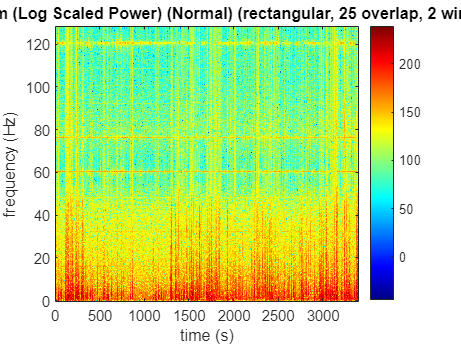



%using our function
[sp1, time, freq]= spectrogram_calculate(EEG_average_non_seizure_signal, ...
    sampling_rate,1,25,2);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (Normal)' ...
    ' (rectangular, 25 overlap, 2 window)']);

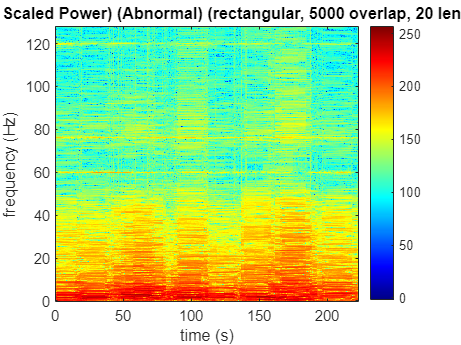


%APPLYING DIFFERENT OVERLAP RATIOS NORMAL

[sp1, time, freq]= spectrogram_calculate(EEG_average_seizure_signal, ...
    sampling_rate,1,5000,20);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (Abnormal)' ...
    ' (rectangular, 5000 overlap, 20 length window)']);

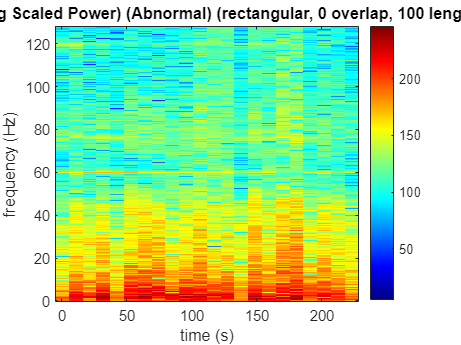


%using our function
[sp1, time, freq]= spectrogram_calculate(EEG_average_seizure_signal, ...
    sampling_rate,1,0,10);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (Abnormal)' ...
    ' (rectangular, 0 overlap, 100 length window)']);

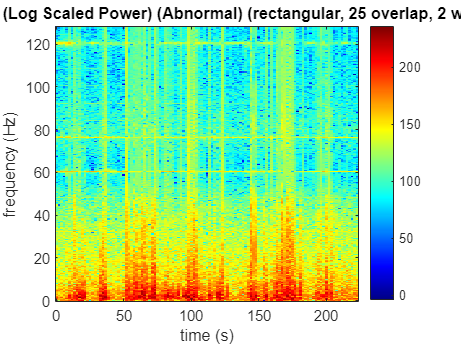



%using our function
[sp1, time, freq]= spectrogram_calculate(EEG_average_seizure_signal, ...
    sampling_rate,1,25,2);
imagesc(time, freq, sp1);
clim auto;
colormap(jet); 
colorbar;  
axis xy; 
xlabel('time (s)'); 
ylabel('frequency (Hz)'); 
title(['Spectrogram (Log Scaled Power) (Abnormal)' ...
    ' (rectangular, 25 overlap, 2 window)']);

function STFT = STFT_calculate(input_signal,sampling_rate_input,window_type, ...
    overlap_value,window_length_value)
    segment_length=sampling_rate_input*window_length_value;
    step_size=segment_length-overlap_value;
    M=segment_length-1;
    t=linspace(0,M,segment_length);
    window_rectangular=ones(1,segment_length);
    window_triangular=[linspace(0,1,segment_length/2),linspace(1,0,segment_length/2)];

    window_hamming=0.54 - 0.46 * cos(2*pi* t/M);
    window_blackman=0.42 - 0.5* cos(2* pi*t/M) + 0.08 * cos(4*pi*t/M);
    windows=[window_rectangular;window_triangular;window_hamming;window_blackman;];
    selected_window=transpose(windows(window_type,:));
    STFT=[];
    for step = segment_length:step_size:length(input_signal)
        lower_index=step-segment_length+1;
        segment=input_signal(lower_index:step);
        windowed_segment=selected_window.*segment;
        STFT_sample=fft(windowed_segment);
        STFT=[STFT,STFT_sample];
    end
end

function [spectrogram, time, freq] = spectrogram_calculate(input_signal,sampling_rate_input, ...
    window_type, overlap_value,window_length_value)


    STFT=STFT_calculate(input_signal,sampling_rate_input,window_type, ...
        overlap_value,window_length_value);
    STFT=STFT(1:height(STFT)/2,:);
    time = linspace(0, length(input_signal)/sampling_rate_input, size(STFT, 2));  
    freq = linspace(0, sampling_rate_input / 2, size(STFT, 1)); 
    spectrogram = 20*log(abs(STFT));
end

%creating a function


